# Optimize Parameters

This code loads and partitions the data.

T = readtable("data\pumpFeatures.csv")

T = 1000×85 table
    wMotor_mean    wMotor_std    wMotor_fftPeakIdx    wMotor_skewness    wMotor_kurtosis    wMotor_peak2peak    wMotor_peak2rms    wMotor_rms    wMotor_mad    wMotor_csRange    wMotor_pLow    wMotor_pMid    wMotor_pHigh    wMotor_pKur    iMotor_mean    iMotor_std    iMotor_fftPeakIdx    iMotor_skewness    iMotor_kurtosis    iMotor_peak2peak    iMotor_peak2rms    iMotor_rms    iMotor_mad    iMotor_csRange    iMotor_pLow    iMotor_pMid    iMotor_pHigh    iMotor_pKur    qIn_mean    

rng(0)
cv = cvpartition(T.faultCode, "Holdout", 0.2);
dataTrain = T(cv.training, :)

dataTrain = 800×85 table
    wMotor_mean    wMotor_std    wMotor_fftPeakIdx    wMotor_skewness    wMotor_kurtosis    wMotor_peak2peak    wMotor_peak2rms    wMotor_rms    wMotor_mad    wMotor_csRange    wMotor_pLow    wMotor_pMid    wMotor_pHigh    wMotor_pKur    iMotor_mean    iMotor_std    iMotor_fftPeakIdx    iMotor_skewness    iMotor_kurtosis    iMotor_peak2peak    iMotor_peak2rms    iMotor_rms    iMotor_mad    iMotor_csRange    iMotor_pLow    iMotor_pMid    iMotor_pHigh    iMotor_pKur    qIn_mean  

dataTest = T(cv.test, :);

This code fits a tree model to the training data and calculates the loss.

holdoutMdl = fitctree(dataTrain, "faultCode");
trainLoss = resubLoss(holdoutMdl)

trainLoss = 0.0125

testLoss = loss(holdoutMdl, dataTest)

testLoss = 0.1343

## Task 1

Set optimization options.

cvpt = cvpartition(dataTrain.faultCode, "KFold", 10);
opt = struct("CVPartition", cvpt, "MaxObjectiveEvaluations", 25);

## Optimize hyperparameters

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize | MaxNumSplits | SplitCriteri-| NumVariables-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | on           | ToSample     |
|===================================================================================================================================|
|    1 | Best   |       0.695 |     0.33196 |       0.695 |       0.695 |          279 |            7 |          gdi |           84 |
|    2 | Best   |        0.13 |     0.31111 |        0.13 |     0.15246 |            4 |          111 |     deviance |           84 |
|    3 | Accept |      0.6925 |     0.15381 |        0.13 |     0.13004 |            4 |            1 |          gdi |           84 |
|    4 | Accept |     0.16375 |     0.18855 |        0.13 |   

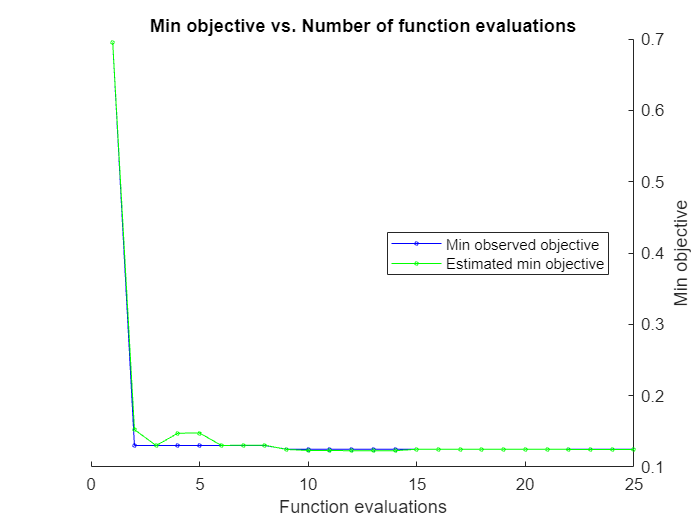


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 25 reached.
Total function evaluations: 25
Total elapsed time: 17.8336 seconds
Total objective function evaluation time: 4.7849

Best observed feasible point:
    MinLeafSize    MaxNumSplits    SplitCriterion    NumVariablesToSample
    ___________    ____________    ______________    ____________________

         1             190            deviance                84         

Observed objective function value = 0.125
Estimated objective function value = 0.1246
Function evaluation time = 0.21896

Best estimated feasible point (according to models):
    MinLeafSize    MaxNumSplits    SplitCriterion    NumVariablesToSample
    ___________    _________

mdl = fitctree(dataTrain, "faultCode",...
    "OptimizeHyperparameters", "all", ...
    "HyperparameterOptimizationOptions", opt);

Calculate loss.

trainLossOptim = resubLoss(mdl)

trainLossOptim = 0.0187

testLossOptim = loss(mdl, dataTest)

testLossOptim = 0.1294

See optimized model parameters.

mdl.ModelParameters

ans =         SplitCriterion: 'deviance'
             MinParent: 10
               MinLeaf: 1
             MaxSplits: 190
          NVarToSample: 'all'
           MergeLeaves: 'on'
                 Prune: 'on'
        PruneCriterion: 'error'
               QEToler: []
            NSurrogate: 0
                MaxCat: 10
                AlgCat: 'auto'
    PredictorSelection: 'allsplits'
          UseChisqTest: 1
                Stream: []
          Reproducible: 0
               Version: 3
                Method: 'Tree'
                  Type: 'classification'
